# 'grid' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create *povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create *camera* object and put it in separate include file to save rendering time in future

pl.include_begin('camera');
    pl.camera('angle', 40, 'location', [-30 -30 15], 'look_at', [0 0 -4], 'type', 'perspective');
    % pl.camera('angle', 35, 'location', [0 0 40], 'look_at', [0 0 0], 'type', 'perspective');
pl.include_end();

#### Create *lights* objects and put them in separate include file to save rendering time in future

% Light
pl.include_begin('lights');
    pl.light('location', [-10 -17 7], 'color', [10 10 10], 'shadowless', true);
    pl.light('location', [-10 10 30],  'color', [2 2 2], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
pl.include_end();

#### Create supplemental helpers objects objects and put them in separate include file to save rendering time in future

% Helpers
pl.include_begin('helpers');
     pl.raw(['sky_sphere{ pigment{ gradient <0,1,0> '...
                          'color_map{ [0   color rgb<0.1, 0.1, 0.1>   ] '...
                                     '[0.4 color rgb<0.1, 0.1, 0.1>] '...
                                     '[0.8 color rgb<0.1, 0.1, 0.1>]  '...
                                     '[1.0 color rgb<0.1, 0.1, 0.1>  ]} '...
                          'scale 2  }}']);
    
pl.include_end();


#### Standard grid

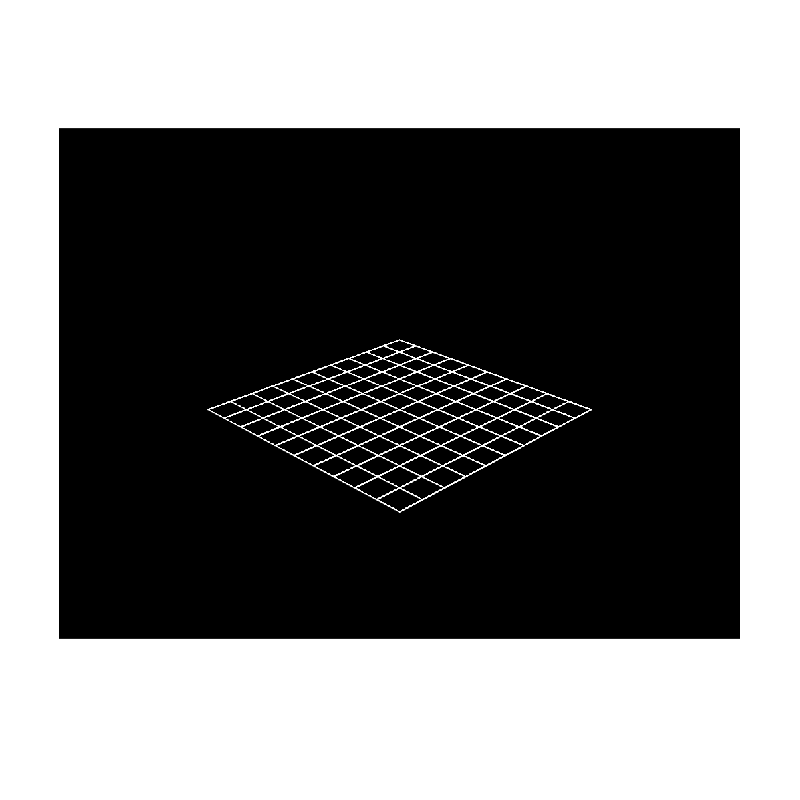

pl.scene_begin('scene_file', 'mesh.pov', 'image_file', 'mesh.png');
    pl.include("camera");
    pl.include("lights");
    %pl.include("helpers");

    pl.grid('width', 10, 'height', 10, 'rotate', [ 90 0 0], 'translate', [-8 -8 0]);

pl.scene_end();

image = pl.render();
imshow(image);

#### **Colored grid**

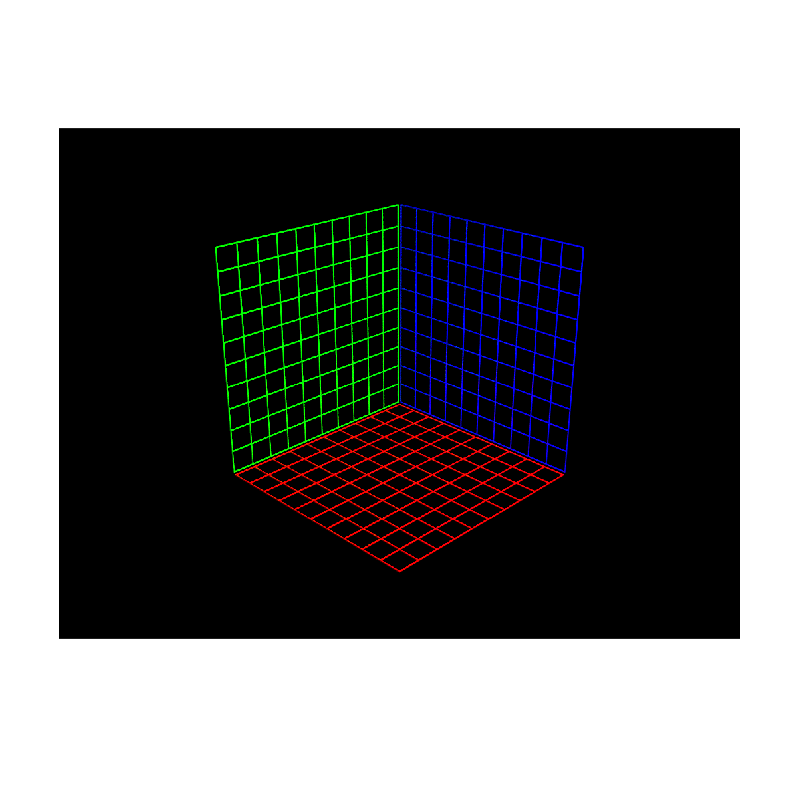


pl.scene_begin('scene_file', 'mesh.pov', 'image_file', 'mesh.png');
    pl.include("camera");
    pl.include("lights");
    % pl.include("helpers");

    tex_grid_gray  = pl.declare("tex_grid_gray",  pl.texture('pigment', [0.5 0.5 0.5], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    tex_grid_red   = pl.declare("tex_grid_red",   pl.texture('pigment', [1.0 0.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    tex_grid_green = pl.declare("tex_grid_green", pl.texture('pigment', [0.0 1.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    tex_grid_blue  = pl.declare("tex_grid_blue",  pl.texture('pigment', [0.0 0.0 1.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    
    pl.grid('width', 10, 'height', 10, 'radius', 0.03,                      'translate', [-5.1 0 0],   'texture_odd', tex_grid_green, 'texture_even', tex_grid_green);
    pl.grid('width', 10, 'height', 10, 'radius', 0.03, 'rotate', [ 0 0 90], 'translate', [0 -5.1 0],   'texture_odd', tex_grid_blue,  'texture_even', tex_grid_blue);
    pl.grid('width', 10, 'height', 10, 'radius', 0.03, 'rotate', [90 0 0],  'translate', [-5.1 -5.1 -5.1], 'texture_odd', tex_grid_red,   'texture_even', tex_grid_red);
    
pl.scene_end();

image = pl.render();
imshow(image);

#### Display elapsed time

toc % Elapsed time

Elapsed time is 3.804269 seconds.
